# **Introduction to MATLAB for Communication Systems I**

# **Author:**

# Amir Mohammad Khoueini

# **Course:**

# Communication Systems I

# **Institution:**

# Department of Electrical Engineering,

# Amirkabir University of Technology (Tehran Polytechnic)

# **Date:**

# September 2025

# **Contact:**

# Telegram: @amohammadkh99

# Email: amirkhoeini99@gmail.com

## 0. Warm Up

Comment block: Select text and press `Ctrl + R`

Uncomment block: Select text and press `Ctrl + T`

%{
This is a block comment

Hello World


that spans multiple lines
Everything between %{ and %} is ignored by MATLAB
You can include as many lines as needed
%}

% Your code here
disp('Hello World');
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% FUNCTION: calculateStatistics
% PURPOSE:  Computes mean and standard deviation
% INPUT:    data - numeric array
% OUTPUT:   mean_val, std_val
% AUTHOR:   Your Name
% DATE:     September 2025
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%{
This section demonstrates data preprocessing
We'll normalize the data and remove outliers
%}

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% DATA PREPROCESSING SECTION

   -0.0373



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
data = randn(100,1);  % Generate random data

% Normalize data (Method 2 style comments)
normalized_data = (data - mean(data)) / std(data);

disp(mean(data))

Commands for Managing

**1. **`clc` - Clears Command Window

It's important to note that `clc` does not clear your workspace variables or your command history—it only affects the visual display of the Command Window.

**When to use it:** Use it at the beginning of scripts or whenever your command window gets cluttered and you want to start with a fresh, empty screen.

% Let's say your command window is full of previous calculations.
% You type:
clc
% Immediately, the command window is cleared, and you only see the prompt: >>

**2. clear** - Removes Variables from Memory (MATLAB workspace)

You can use it to clear all variables or specify specific ones to remove.

**When to use it:** Use it when you want to start a fresh computation without any old variables interfering, or when you need to free up memory from large data sets.

% Create some variables
a = 10;
b = rand(1000); % A large 1000x1000 matrix
myData = 'Hello World';

% Clear a specific variable (e.g., the large matrix 'b')
clear b
% Now, only 'a' and 'myData' remain in the workspace.

% Clear all variables from the workspace
clear
% The workspace is now completely empty.

**3.** **help**

Displays detailed, official documentation for a specific MATLAB function, toolbox, or concept directly in the Command Window.

**When to use it:** Whenever you need to quickly check the syntax, input arguments, output arguments, or usage examples for a function you know the name of.

% Get help for the 'plot' function
% The command window will display a detailed description of how to use 'plot',
% including all its possible line styles, color options, and input formats.
help plot

 plot   Linear plot. 
    plot(X,Y) plots vector Y versus vector X. If X or Y is a matrix,
    then the vector is plotted versus the rows or columns of the matrix,
    whichever line up.  If X is a scalar and Y is a vector, disconnected
    line objects are created and plotted as discrete points vertically at
    X.
 
    plot(Y) plots the columns of Y versus their index.
    If Y is complex, plot(Y) is equivalent to plot(real(Y),imag(Y)).
    In all other uses of plot, the imaginary part is ignored.
 
    Various line types, plot symbols and colors may be obtained with
    plot(X,Y,S) where S is a character string made from one element
    from any or all the following 3 columns:
 
           b     blue          .     point              -     solid
           g     green         o     circle             :     dotted
           r     red           x     x-mark         

**4. lookfor**

This command searches through the first line of help text (the H1 line) for all MATLAB functions for a specified keyword. It's useful when you don't know the exact name of a function but know what you want to do.

**When to use it:** When you are looking for a function related to a specific topic (e.g., "fft", "graph", "integral").

% Search for all functions that have "Fourier" in their brief description
% This might return:
% FFT - Discrete Fourier transform.
% IFFT - Inverse discrete Fourier transform.
% FFTSHIFT - Shift zero-frequency component to center of spectrum.
% ... and many more
lookfor Fourier

dftmtx                         - Discrete Fourier transform matrix in Galois field
fft                            - Fast Fourier transform of Galois field vector
ifft                           - Inverse fast Fourier transform of Galois field vector
fourierBasis                   - Fourier basis functions for tunable gain surface
dsp.FFT                        - Discrete Fourier transform
dsp.IFFT                       - Inverse discrete Fourier transform (IDFT)
FFT                            - Fast Fourier transform (FFT) of input
IFFT                           - Inverse fast Fourier transform (IFFT) of input


**5. pwd (Print Working Directory)**

 tells you your current folder. MATLAB can only "see" files in this folder and on its path.

pwd

ans = 'C:\Users\amirk\Documents\MATLAB'

**6. cd (Change Directory)**

changes your current folder.

cd 'C:\Users\amirk\Documents\MATLAB'
pwd

ans = 'C:\Users\amirk\Documents\MATLAB'

**7. dir**

 lists all files and folders. It's the equivalent of the `ls` or `dir` command in a system terminal.

dir

.                                  ..                                 Communication_Systems_1_Intro.mlx  Examples                           my_data.mat                        my_session_log.txt                 my_time_data.mat                   myfile.mat                         test.m                             



**8. what**

`what` is more specialized. It lists only files relevant to MATLAB (like .m, .mat, .mlx, .fig files) and conveniently groups them by type.

what

MATLAB Code files in the current folder C:\Users\amirk\Documents\MATLAB

test  

MATLAB Live Code in the current folder C:\Users\amirk\Documents\MATLAB

Communication_Systems_1_Intro  

MAT-files in the current folder C:\Users\amirk\Documents\MATLAB

my_data       my_time_data  myfile        




**9. **`load`** & **`save`

`save` stores all variables from your Workspace into a `.mat` file for later use.

`load` reads a `.mat` file and puts all the variables back into your Workspace.

clear
velocity = [10, 15, 22, 18, 9];
time = 0:0.1:1;
% Save ALL workspace variables to a file called 'my_data.mat'
save('my_data.mat')
% Save only specific variables
save('my_time_data.mat', 'time')

% Clear the entire workspace to simulate starting a new session
clear

% Now load the data back in
load('my_data.mat')
% The variable time' are now back in your workspace.

% You can also load data directly into a variable (useful for large files)
my_loaded_data = load('my_time_data.mat');
% Now you access the variables as fields of a struct: my_loaded_data.velocity
time2 = my_loaded_data.time;

**10.** `disp`** (Display)**

The simplest way to output text or the value of a variable

Displaying a simple string:

disp('Hello, World!');

Hello, World!


Displaying a variable's value:

name = 'Alice';
disp(name);

Alice


% Display a numeric array
x = [1, 2, 3, 4];
disp(x);

     1     2     3     4



Combining text and numbers (requires `num2str` for conversion):

Use `num2str` to convert numbers to strings for concatenation in messages.

Note: This uses array concatenation with square brackets []

age = 30;
disp([name, ' is ', num2str(age), ' years old.']);

Alice is 30 years old.


**11.** `fprintf`** (Formatted Print)**

It gives you precise control over how text, numbers, and variables are displayed. 

- `%s` : String

- `%d` : Integer (digit)

- `%f` : Floating-point number [Controlling decimal precision (`%0.2f` means 2 digits after decimal)]

- `\n` : New line

- `\t` : Tab

name = 'Bob';
score = 95.678;
fprintf('%s scored %.2f points.\n', name, score);

Bob scored 95.68 points.


**12. input**

To pause the program and get a value from the user

- `x = input(prompt)` : For numerical input.

- `str = input(prompt, 's')` : For string input (exactly as the user types it).

% Get a number from the user
age = input('Enter your age: ');

% Get a string from the user
name = input('Enter your name: ', 's');

% Use the input
fprintf('Hello, %s! You are %d years old.\n', name, age);

Hello, Amir! You are 20 years old.


a = [1 2 3 4 5 6 9 8 7]

a =      1     2     3     4     5     6     9     8     7


Once it is executed you will see vector **a** in workspace.

b = 0:2:20

b =      0     2     4     6     8    10    12    14    16    18    20


`linspace` - Generates a vector with linearly spaced elements between two values.

c = linspace(0,1,10)  % 10 points from 0 to 10

c =          0    0.1111    0.2222    0.3333    0.4444    0.5556    0.6667    0.7778    0.8889    1.0000


d = [1 2 3; 4 5 6; 7 8 9]

d =      1     2     3
     4     5     6
     7     8     9


A = [1, 2; 3, 4];
B = [5, 6; 7, 8];
C = cat(2, A, B); % Concatenate horizontally (dimension 2)
disp(C)

     1     2     5     6
     3     4     7     8



D = cat(1,A, B);  % Concatenate vertically (dimension 1)
disp(D);

     1     2
     3     4
     5     6
     7     8



d^2

ans =     30    36    42
    66    81    96
   102   126   150


d.^2

ans =      1     4     9
    16    25    36
    49    64    81


e = [0.5+0.5i, 1i, 1, -0.5+1i; -0.7, 0.3+0.5i, 1.2-0.5i, 0.8; 0.6i, -0.8, -0.2+0.9i, 0.4i]

e =    0.5000 + 0.5000i   0.0000 + 1.0000i   1.0000 + 0.0000i  -0.5000 + 1.0000i
  -0.7000 + 0.0000i   0.3000 + 0.5000i   1.2000 - 0.5000i   0.8000 + 0.0000i
   0.0000 + 0.6000i  -0.8000 + 0.0000i  -0.2000 + 0.9000i   0.0000 + 0.4000i


### **The Left-Division Operator**

Purpose: Solves the system of linear equations $Ax=B$

This is mathematically equivalent to x = inv(A) * B; but it is vastly superior to using `inv(A)`. Instead of actually calculating the inverse (which is computationally expensive and less accurate), MATLAB uses highly efficient and numerically stable methods like LU decomposition, Cholesky decomposition, or QR decomposition depending on the properties of matrix `A.`

Example:

Solve the system:


$$2x + y = 5$$



$$x - 3y = -1$$


In matrix form, this is `A * x = B`:

A = [2 1; 1 -3];
B = [5; -1];
x = A \ B

x =      2
     1


### The format Command

By default, MATLAB displays numbers with four decimal place values. This is known as **short format**.

However, if you want more precision, you need to use the **format** command.

The **format long** command displays 16 digits after decimal.

format long
x = 7 + 10/3 + 5 ^ 1.2

x =   17.231981640639408


format short
x = 7 + 10/3 + 5 ^ 1.2

x = 17.2320

The **format bank** command rounds numbers to two decimal places.

format bank
x = 177.457389

x =         177.46


MATLAB displays large numbers using exponential notation.

The **format short e** command allows displaying in exponential form with four decimal places plus the exponent.

format short e
x = 4.678 * 4.9

x =    2.2922e+01


The **format rat** command gives the closest rational expression

format rat
x= 4.678 * 4.9

x =     2063/90    


format("default")
clear all;
A = [1 2 3 4; 5 6 7 8; 9 10 11 12; 13 14 15 16]

A =      1     2     3     4
     5     6     7     8
     9    10    11    12
    13    14    15    16


A(4,2)

ans = 14

A(1:3,2)

ans =      2
     6
    10


A(3,:)

ans =      9    10    11    12


A > 8

ans = 4×4 logical array
   0   0   0   0
   0   0   0   0
   1   1   1   1
   1   1   1   1


A(A > 8)

ans =      9
    13
    10
    14
    11
    15
    12
    16


A .* (A > 8)

ans =      0     0     0     0
     0     0     0     0
     9    10    11    12
    13    14    15    16


You can view the contents of the workspace using `whos`.

The variables also appear in the Workspace panel on the desktop.

whos

  Name      Size            Bytes  Class     Attributes

  A         4x4               128  double              
  ans       4x4               128  double              



Workspace variables do not persist after you exit MATLAB. Save your data for later use with the `save` command,

Saving preserves the workspace in your current working folder in a compressed file with a `.mat` extension, called a MAT-file.

Restore data from a MAT-file into the workspace using `load`.

a = 10;
% while loop execution
while (a < 20 )
fprintf('value of a: %d\n', a);
a = a+1;
if( a > 15)
% terminate the loop using break statement
break;
end
end

value of a: 10
value of a: 11
value of a: 12
value of a: 13
value of a: 14
value of a: 15


N = 100;
f(1) = 1;
f(2) = 1;

for n = 3:N
    f(n) = f(n-1) + f(n-2);
end
f(1:10)

ans =      1     1     2     3     5     8    13    21    34    55


## 1. Defining and Plotting Signals

- Show continuous-time signals via sampled vectors.

- Example: sinusoids, exponentials, rectangular pulse.

- `figure `Opens a new, separate window for a plot. This is crucial when you want to create multiple plots without overwriting the previous one.

- `plot(x,y): `The fundamental command for creating 2D line plots.

- `stem(n,y): `Creates a discrete "stem" plot, perfect for representing digital signals or sequences.

- `xlabel('')`, `ylabel(''): `Adds labels to your axes

- `grid on: `Adds grid lines to the plot, making it easier to read values.

- `axis([xmin xmax ymin ymax]): `Controls the visible range of the axes. Extremely useful for zooming in on a specific part of your data.

- `hold on: `"Holds" the current plot so that new plots are added to the existing one, instead of replacing it. Critical for plotting multiple datasets on the same axes.

- `legend`:  Adds a legend to identify the different plots.

- `subplot: `Creates an array of smaller, separate plots (subplots) within a single figure window. Great for comparing results side-by-side.

- `title(''): `Adds text at the top of the plot

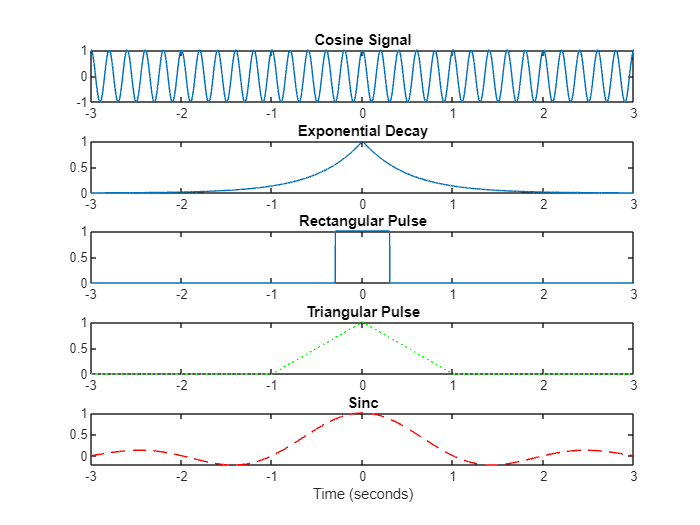

% Time axis
fs = 1000;              % Sampling frequency (Hz)
t = -3:1/fs:3;  
% N = 1000;             % Number of samples
% t = linspace(-3,3,N); % Define the time axis based on the number of samples
% Ts = t(2) - t(1);

% Define signals
f = 5;                  % 5 Hz cosine signal
x1 = cos(2*pi*f*t);     
x2 = exp(-2*abs(t));    % exponential decay
x3 = (abs(t) < 0.3);    % rectangular pulse
x4 = (abs(t) < 1) .* (1 - abs(t));
x5 = sinc(t);

% Plot
figure;
subplot(5,1,1); plot(t,x1); title('Cosine Signal');
subplot(5,1,2); plot(t,x2); title('Exponential Decay');
subplot(5,1,3); plot(t,x3); title('Rectangular Pulse');
subplot(5,1,4); plot(t,x4, "g:"); title('Triangular Pulse');
subplot(5,1,5); plot(t,x5,"r--"); title('Sinc');
xlabel('Time (seconds)');

We can define continuous-time dirac delta function as follows:

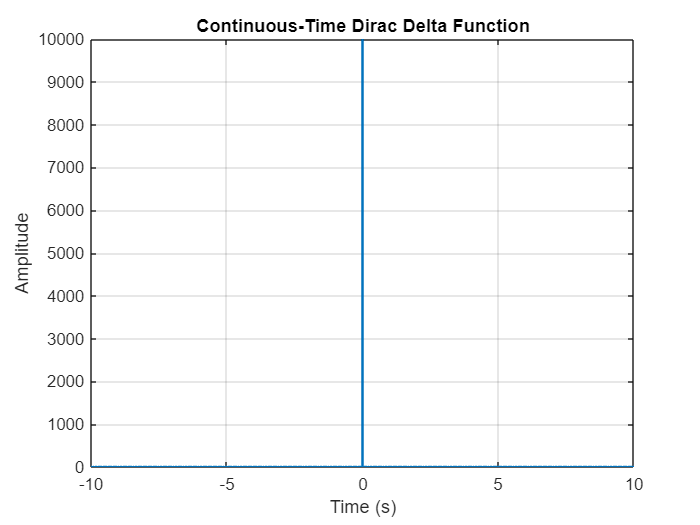

fs = 1e4;
ts = 1/fs;
t = -10:ts:10;
N = length(t);
delta = zeros(N, 1);
% Spike at t = 0
delta(t == 0) = fs; 
plot(t, delta, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Continuous-Time Dirac Delta Function');
grid on;

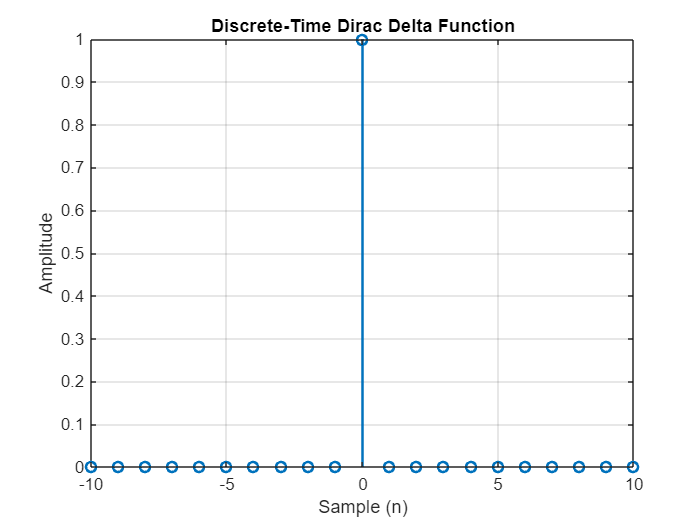

n = -10:10;
N = length(n);
delta = zeros(N, 1);
delta(n == 0) = 1;
stem(n, delta, 'LineWidth', 1.5);
xlabel('Sample (n)');
ylabel('Amplitude');
title('Discrete-Time Dirac Delta Function');
grid on;

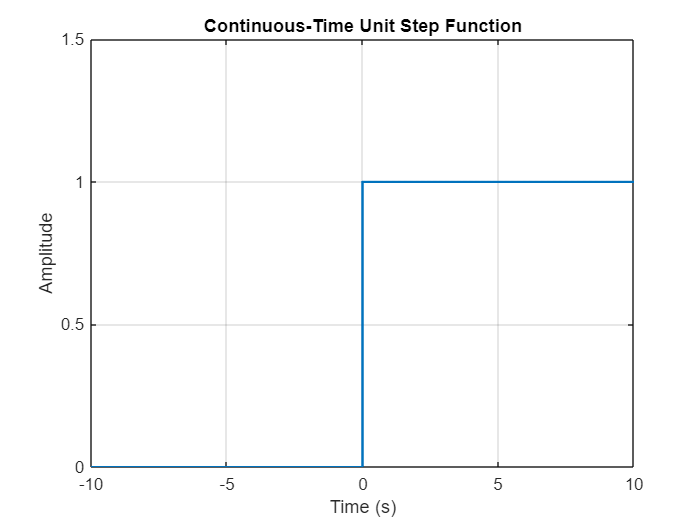

fs = 1e3;
ts = 1/fs;
t = -10:ts:10;
% Heaviside function
unit_step = heaviside(t); 
plot(t, unit_step, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Continuous-Time Unit Step Function');
ylim([0, 1.5])
grid on;

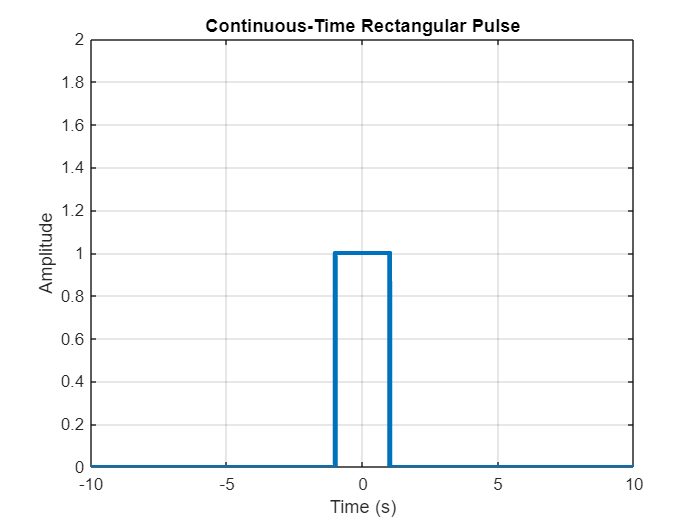

fs = 1e3;
ts = 1/fs;
t = -10:ts:10;
% Rectangular pulse with width 2
rect_pulse = rectpuls(t, 2); 
plot(t, rect_pulse, 'LineWidth', 3);
xlabel('Time (s)');
ylabel('Amplitude');
title('Continuous-Time Rectangular Pulse');
ylim([0,2])
grid on;

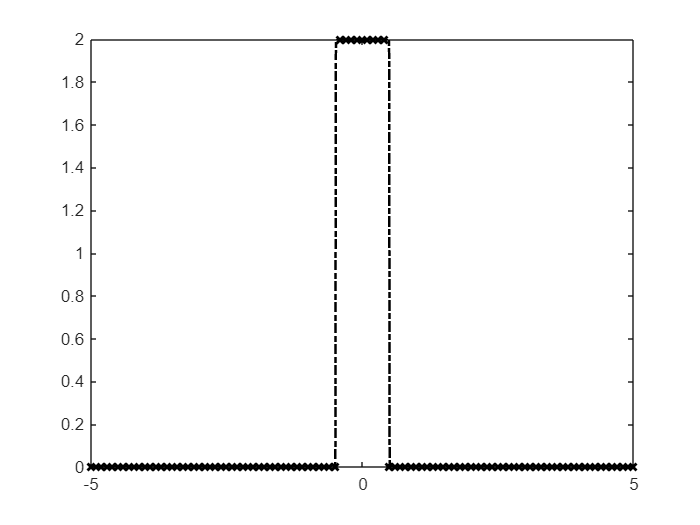

T0 = -5;
Tf = +5;
fs = 100;
Ts = 1/fs;
t = T0:Ts:Tf;
x = 2*(t > -0.5) .* (t < 0.5);
figure;
plot(t,x, Color="k", LineWidth=1.5, LineStyle="-.", Marker="x", MarkerIndices=1:10:length(x));

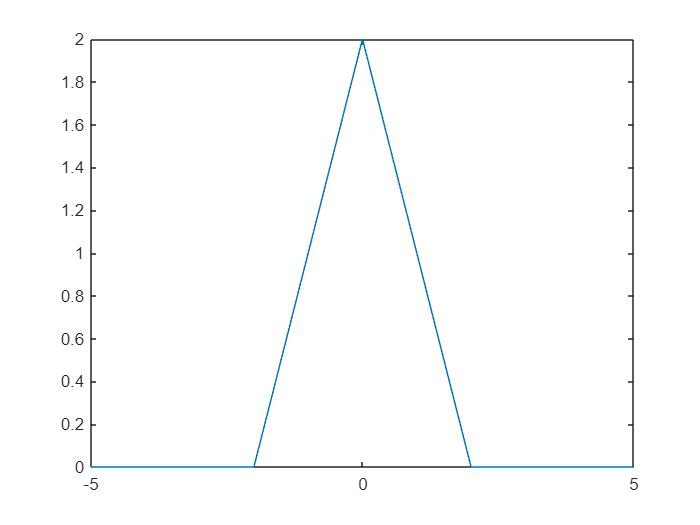

T0 = -5;
Tf = +5;
fs = 100;
Ts = 1/fs;
t = T0:Ts:Tf;
x = (t+2).*(t>=-2).*(t<0) + (2-t).*(t>=0).*(t<=2);
figure;
plot(t,x);

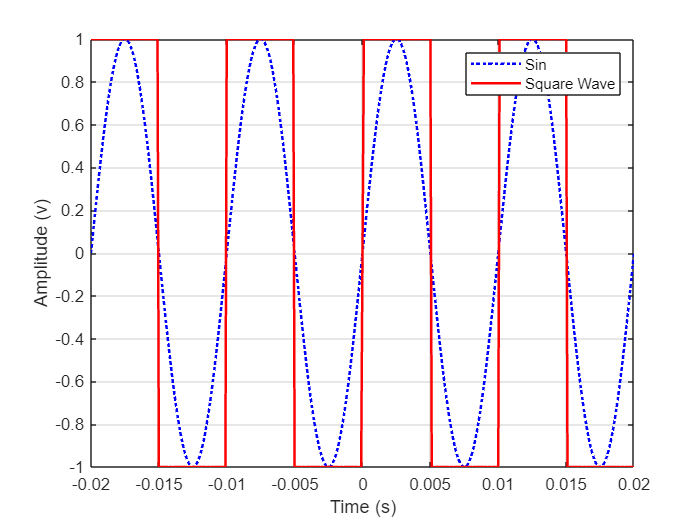

fm = 100;
fs = 100*fm;
Ts = 1/fs;
T0 = -2/fm;
Tf = 2/fm;
t = T0:Ts:Tf;
x1 = sin(2*pi*fm*t);
x2 = sign(x1);
figure;
plot(t, x1, 'b:', t, x2, 'r', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Amplitude (v)')
legend('Sin', 'Square Wave')


$$z=f(x,y)$$


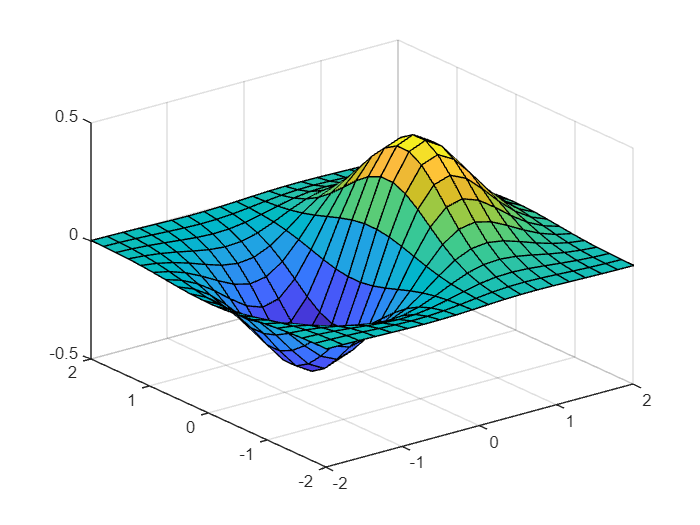

figure
x = linspace(-2,2,20);
y = x';
z = x .* exp(-x.^2 - y.^2);
surf(x,y,z)

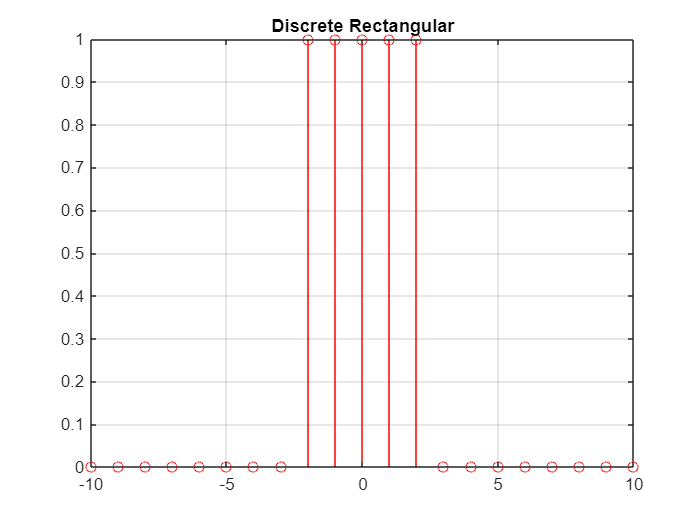

% Discrete time vector (n = -10 to 10)
n = -10:10;

% Rectangular: 1 for |n| <= 2 (width=5 samples)
rect = (abs(n) <= 2);



% Plot
figure;
stem(n, rect, 'r'); 

title('Discrete Rectangular'); 
grid on;

Discrete-time signals are made by sampling continuous-time signals (Although in MATLAB continuoustime signals are discrete-time signals with very small sampling time).  

We use `stem` function to visualize discrete-time signals.

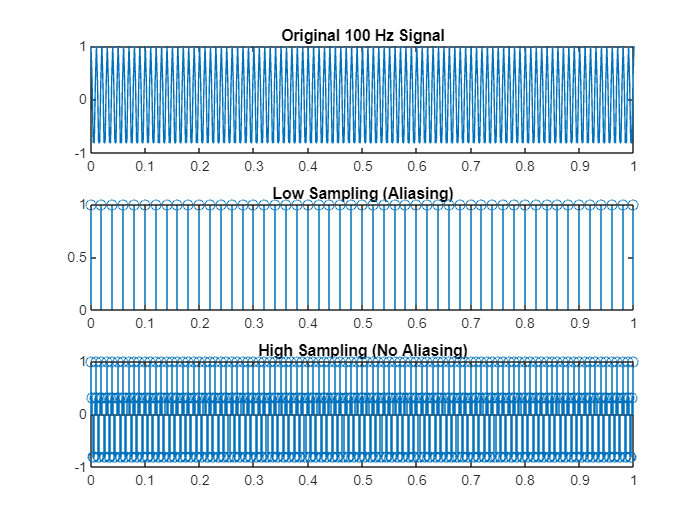

% Repeat for others or use subplot for all
Fs1 = 50;               % Low sampling rate
Fs2 = 500;              % High sampling rate
t1 = 0:1/Fs1:1; 
t2 = 0:1/Fs2:1;

x = cos(2*pi*100*t2);  % Original signal

x1 = cos(2*pi*100*t1); % Sampled low
x2 = cos(2*pi*100*t2); % Sampled high

figure;
subplot(3,1,1); 
plot(t2,x); 
title('Original 100 Hz Signal');
subplot(3,1,2); 
stem(t1,x1); 
title('Low Sampling (Aliasing)');
subplot(3,1,3); 

stem(t2,x2); 
title('High Sampling (No Aliasing)');

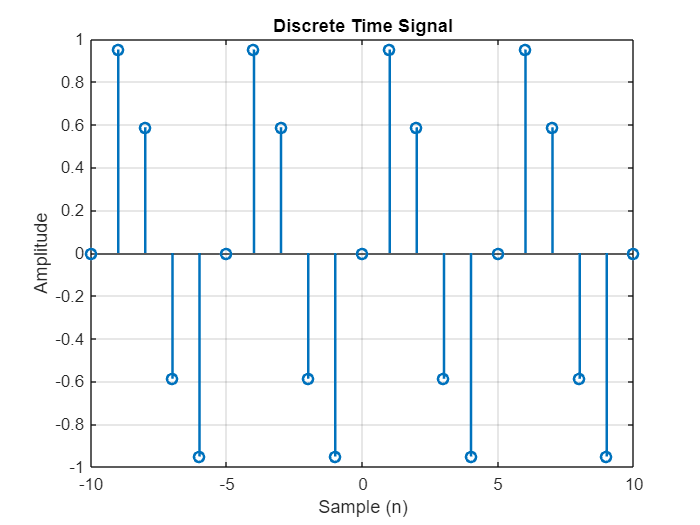

n = -10:10;
xn = sin(2 * pi * n / 5);
figure('Name', 'Discrete Signal');
stem(n, xn, 'LineWidth', 1.5);
xlabel('Sample (n)');
ylabel('Amplitude');
title('Discrete Time Signal');
grid on;

We can also use `stairs `function to visualize discrete-time signals. The `stairs `function is similar to `stem `function. The only difference is that the `stairs `function draws a continuous line between the samples. 

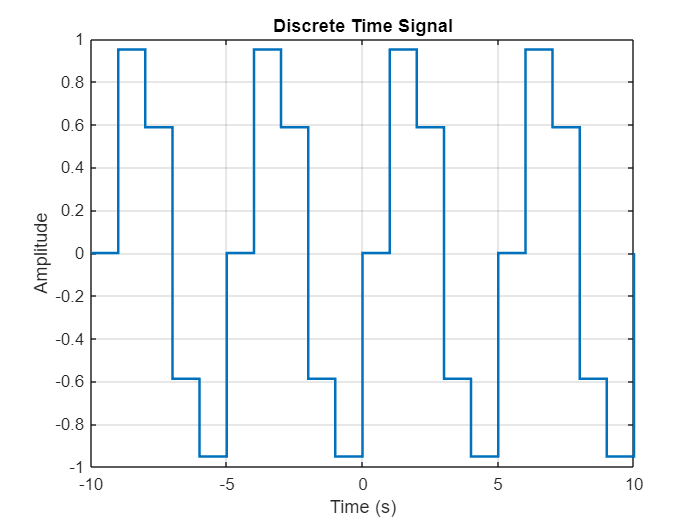

figure();
stairs(n, xn, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Discrete Time Signal');
grid on;

## 2. Signal Operations & Transformations

- Time shifting, scaling, addition, multiplication, convolution.

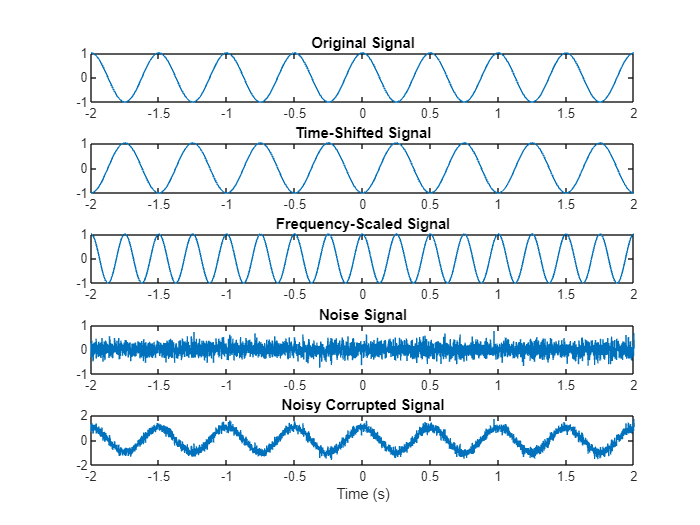

t = -2:0.001:2;
x = cos(2*pi*2*t);                  % Original signal

% Time shift and scaling
x_shift = cos(2*pi*2*(t-0.75));     % delayed version of the signal
x_scale = cos(2*pi*4*t);            % frequency scaling
noise = 0.2*randn(size(t));
x_noisy = x + noise;   % Add noise

% Plot
figure;
subplot(5,1,1); plot(t,x); title('Original Signal');
subplot(5,1,2); plot(t,x_shift); title('Time-Shifted Signal');
subplot(5,1,3); plot(t,x_scale); title('Frequency-Scaled Signal');
subplot(5,1,4); plot(t, noise); title('Noise Signal');
subplot(5,1,5); plot(t, x_noisy); title('Noisy Corrupted Signal');
xlabel('Time (s)');

signal_power = mean(x.^2);
noise_power = mean(noise.^2);
SNR_dB = 10*log10(signal_power / noise_power);
disp(['SNR: ', num2str(SNR_dB), ' dB']);

SNR: 10.8931 dB


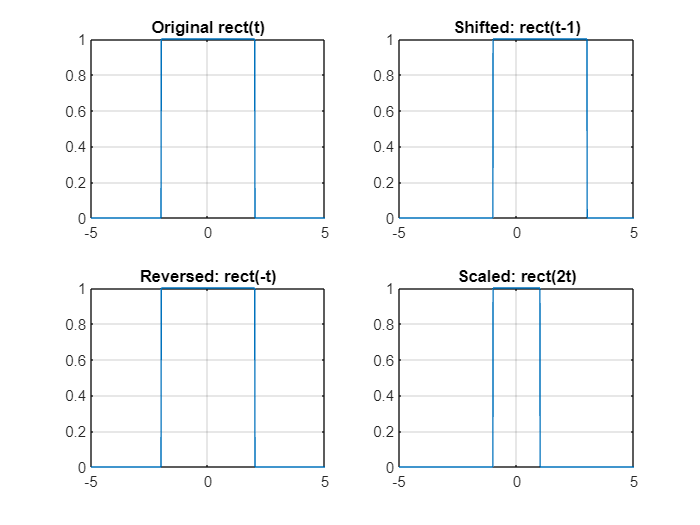

t = linspace(-5, 5, 1000);
rect = (abs(t) < 2);

% Time Shifting: rect(t - t0), shift right by t0=1
t0 = 1;
rect_shifted = (abs(t - t0) < 2);

% Time Reversal: rect(-t)
rect_reversed = (abs(-t) < 2);  % Equivalent to original for symmetric, but demo general

% Time Scaling: rect(2*t), compress by factor 2 (narrower)
rect_scaled = (abs(2*t) < 2);

% Plot
figure;
subplot(2,2,1); plot(t, rect); title('Original rect(t)'); grid on;
subplot(2,2,2); plot(t, rect_shifted); title('Shifted: rect(t-1)'); grid on;
subplot(2,2,3); plot(t, rect_reversed); title('Reversed: rect(-t)'); grid on;
subplot(2,2,4); plot(t, rect_scaled); title('Scaled: rect(2t)'); grid on;

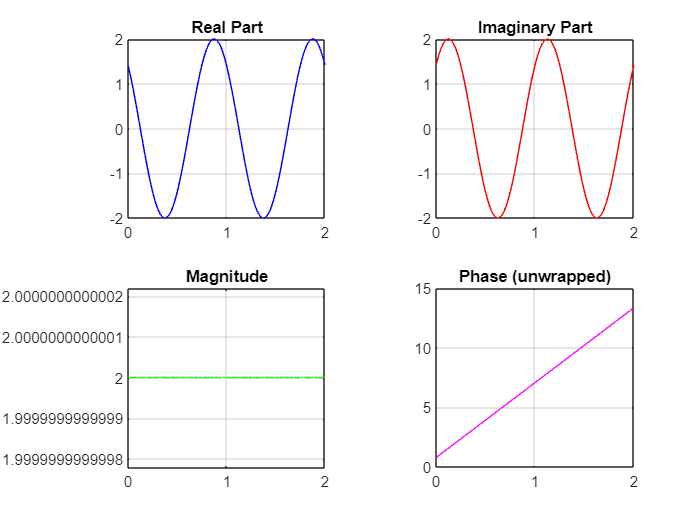

% Parameters
A = 2;                           % Amplitude
f0 = 1;                          % Frequency (Hz)
theta = pi/4;                    % Phase (radians)
t = linspace(0, 2, 1000);        % Time vector, 2 periods

% Complex signal: A * exp(j * (2*pi*f0*t + theta))
s_complex = A * exp(1j * (2*pi*f0*t + theta));

% Real and Imaginary parts
real_part = real(s_complex);
imag_part = imag(s_complex);

% Magnitude: |s(t)| = A (constant for pure exponential)
magnitude = abs(s_complex);

% Phase: angle(s(t)) = 2*pi*f0*t + theta (unwrapped)
phase = unwrap(angle(s_complex));

% Plot
figure;
subplot(2,2,1); plot(t, real_part, 'b'); title('Real Part'); grid on;
subplot(2,2,2); plot(t, imag_part, 'r'); title('Imaginary Part'); grid on;
subplot(2,2,3); plot(t, magnitude, 'g'); title('Magnitude'); grid on;
subplot(2,2,4); plot(t, phase, 'm'); title('Phase (unwrapped)'); grid on;

## 3. Solving Integrals: Symbolically and Monte-Carlo (Numerically)

Numerical integration is used when:

- The function is known only by its values at specific points (e.g., data from an experiment).

- The function is too complex to integrate symbolically ("non-integrable").

- You only need a numerical answer, not a formula.

MATLAB offers several functions, but the most common and versatile are `integral()` and `trapz()`.

fs = 10000;
t = -2:1/fs:2;
x = sin(t).^2;

integral1 = trapz(t, x)   % Numerical integration

integral1 = 2.3784

integrand = @(t) sin(t).^2;
integral(integrand, -2, 2)

ans = 2.3784

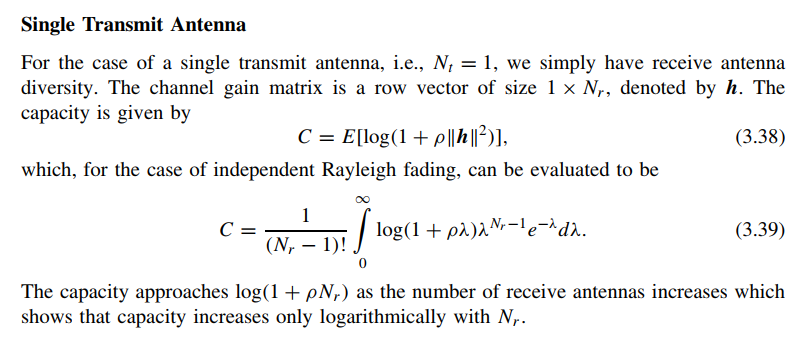

rho_dB = 10;          % SNR = 10 dB
rho = 10^(rho_dB/10); % Convert to linear scale
Nr = 4;               % 4 receive antennas
integrand = @(lambda) log2(1 + rho*lambda) .* (lambda.^(Nr-1)) .* exp(-lambda) / factorial(Nr-1);
% Numerical integration from 0 to Inf
C = integral(integrand, 0, Inf)

C = 5.1811

syms t;
x = sin(t)^2;
integral2 = int(x,t,-2, 2)

$$integral2 = 2-\frac{\sin\left(4\right)}{2}$$

F_indefinite = int(x, t)

$$F\_indefinite = \frac{t}{2}-\frac{\sin\left(2\,t\right)}{4}$$

a = -2; b = 2; N = 1e6;  % Samples
t_rand = a + (b-a)*rand(N,1);
samples = sin(t_rand).^2;
integral3 = (b-a) * mean(samples)

integral3 = 2.3765

integrand = @(x) exp(-x.^2);
area = integral(integrand, 0, 1)

area = 0.7468

syms x
eqn = x^2 - 5*x + 6 == 0;
sol = solve(eqn, x)

$$sol = \left(\begin{array}{c} 2\\ 3 \end{array}\right)$$

syms x y
eq1 = x + y == 5;
eq2 = x - y == 1;
sol = solve([eq1, eq2], [x, y])

sol = struct with fields:
    x: 3
    y: 2


syms a b c d
A = [a, b; c, d];
det_A = det(A)        

$$det\_A = a\,d-b\,c$$

inv_A = inv(A)        

$$inv\_A = \left(\begin{array}{cc} \frac{d}{a\,d-b\,c} & -\frac{b}{a\,d-b\,c}\\ -\frac{c}{a\,d-b\,c} & \frac{a}{a\,d-b\,c} \end{array}\right)$$

% Transfer function analysis
syms s t
G = 1/(s^2 + 2*s + 1);  % Transfer function

% Inverse Laplace transform for time response
g_t = ilaplace(G)

$$g\_t = t\,{\mathrm{e}}^{-t}$$

## 4. Convolution

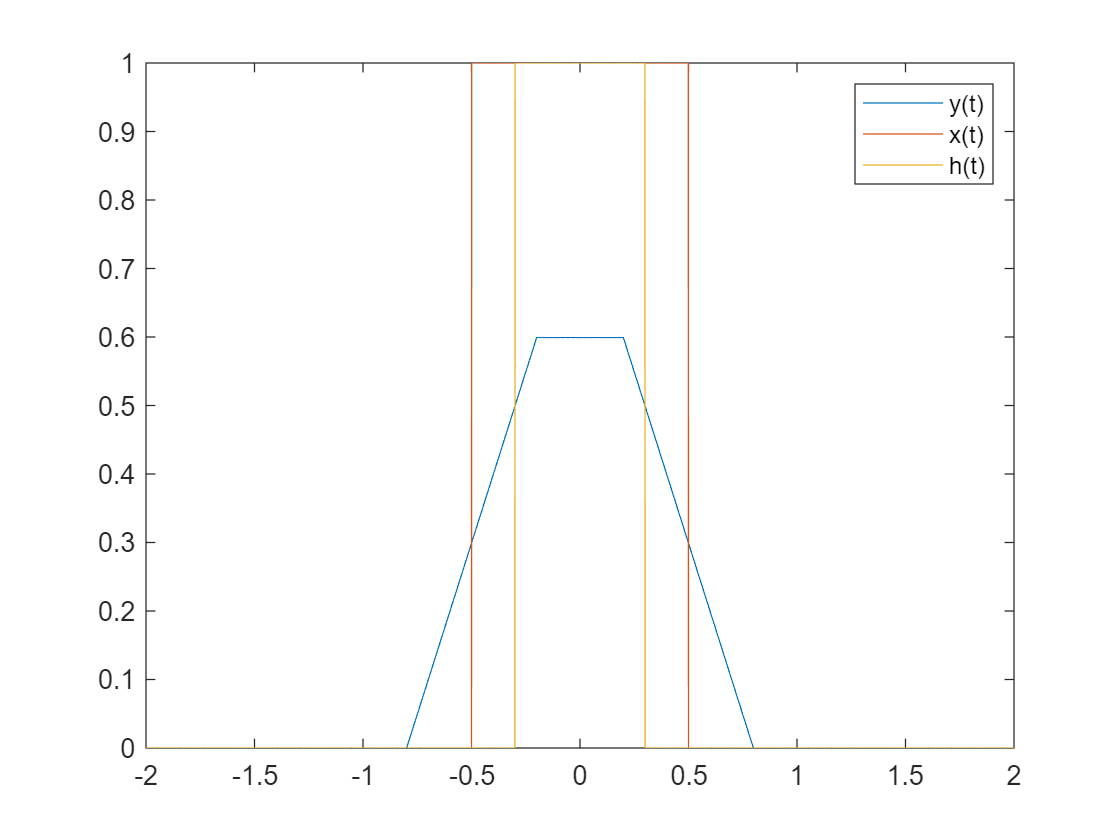

fs = 1000;
t = -2:1/fs:2;
x = (abs(t)<0.5);      % Rectangular pulse
h = (abs(t)<0.3);      % Another pulse

y = conv(x,h,'same')*(1/fs); % Convolution

figure;
plot(t,y);
hold on;
plot(t,x);
plot(t,h);
legend('y(t)', 'x(t)', 'h(t)')

xlim("auto")
ylim("auto")

## 5. Fourier Transform

- `fourier()` - Symbolic Fourier transform computes the continuous Fourier transform (analytical)

- `fft()` - computes Discrete Fourier Transform (DFT) with Fast Fourier Transform algorithm (numeric computation)

In MATLAB the DFT is implemented by the function `fft`. The inverse DFT is implemented by the function `ifft`. In MATLAB index of the first element of a vector is 1. So, the DFT formula in MATLAB is


$$X[k] = \sum_{n=1}^{N} x[n] e^{-j\frac{2\pi}{N}kn}.$$


Also, the inverse DFT formula in MATLAB is


$$x[n] = \frac{1}{N} \sum_{k=1}^{N} X[k] e^{j\frac{2\pi}{N}kn}.$$


#### Fourier Series of a Discrete-time Periodic Signal

The Fourier series of a discrete-time periodic signal $x[n]$ is defined as


$$x[n] = \sum_{k=0}^{N-1} X[k] e^{j\frac{2\pi}{N}kn}$$


where $N$ is the period of the signal.

The inverse Fourier series is defined as


$$X[k] = \frac{1}{N} \sum_{n=0}^{N-1} x[n] e^{-j\frac{2\pi}{N}kn}.$$


The Fourier series of a discrete-time periodic signal is the DFT of the signal. So, the Fourier series of a discrete-time periodic signal can be computed by the command `fft`. The inverse Fourier series is the inverse DFT of the signal. So, the inverse Fourier series of a discrete-time periodic signal can be computed by the command `ifft`.

syms t omega
x = cos(2*pi*50*t) + cos(2*pi*120*t);
X = fourier(x, t, omega);
disp(X);

$$\pi \,\left(\delta (\omega -100\,\pi )+\delta (\omega +100\,\pi )\right)+\pi \,\left(\delta (\omega -240\,\pi )+\delta (\omega +240\,\pi )\right)$$

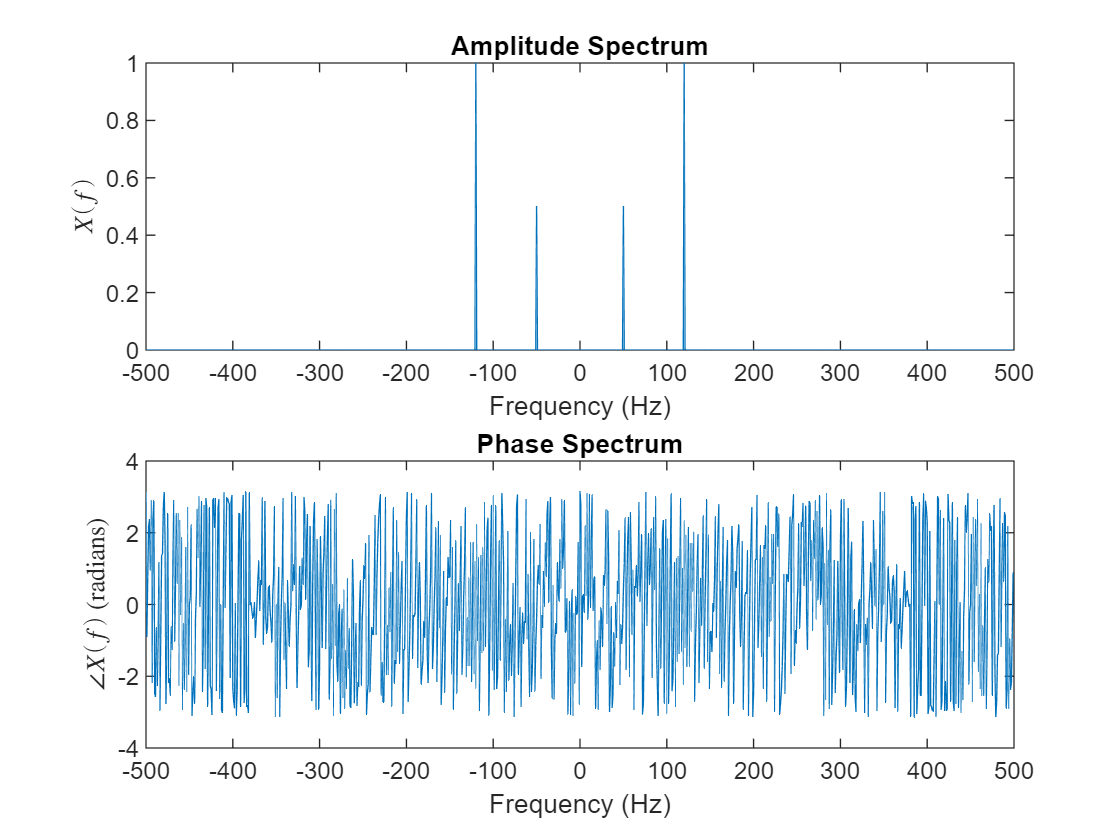

fs = 1000;             % Sampling frequency
t = 0:1/fs:1-1/fs; 
f1 = 50;
f2 = 120;
x = cos(2*pi*f1*t) + 2*cos(2*pi*f2*t);

% FFT
N = length(x);
X = fftshift(fft(x))/fs;

% frequency axis
omega = 2*pi/N * (-N/2:N/2-1);
f = (omega/(2*pi)) * fs;
% f = (-N/2:N/2-1)*(Fs/N); 
% f = linspace(-fs/2, fs/2, N); 

% Spectrum
figure;
subplot(2,1,1);
plot(f,abs(X));
title('Amplitude Spectrum'); 
xlabel('Frequency (Hz)'); 
ylabel('$X(f)$', 'Interpreter', 'latex')

subplot(2,1,2);
plot(f,angle(fftshift(X)));
title('Phase Spectrum');
xlabel('Frequency (Hz)');
ylabel('$\angle X(f)$ (radians)', 'Interpreter', 'latex')

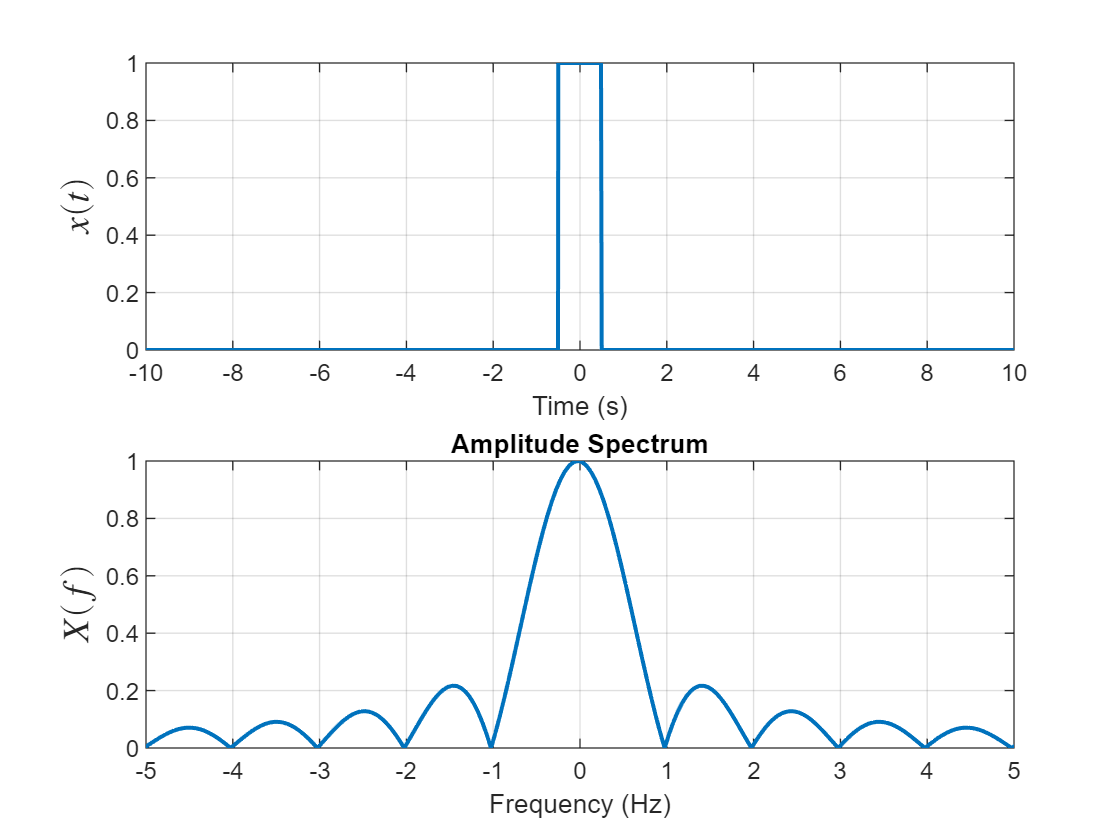

T0 = -10;
Tf = +10;
fs = 100e3;
Ts = 1/fs;
t = T0:Ts:Tf;
x = 1.*(t > -0.5) .* (t < 0.5);

% FFT
N = length(x);
X = fftshift(fft(x))/fs;

% Frequency axis
omega = 2*pi/N * (-N/2:N/2-1);
f = (omega/(2*pi)) * fs;

% Spectrum
figure;
subplot(2,1,1)
plot(t, x, LineWidth=1.5)
xlabel('Time (s)');
ylabel('$x(t)$', 'Interpreter', 'latex','FontSize',14)
grid on

subplot(2,1,2)
plot(f,abs(X), "LineWidth",1.5);
title('Amplitude Spectrum');
xlabel('Frequency (Hz)');
ylabel('$X(f)$', 'Interpreter', 'latex', 'FontSize',14)
grid on;
xlim([-5, 5])

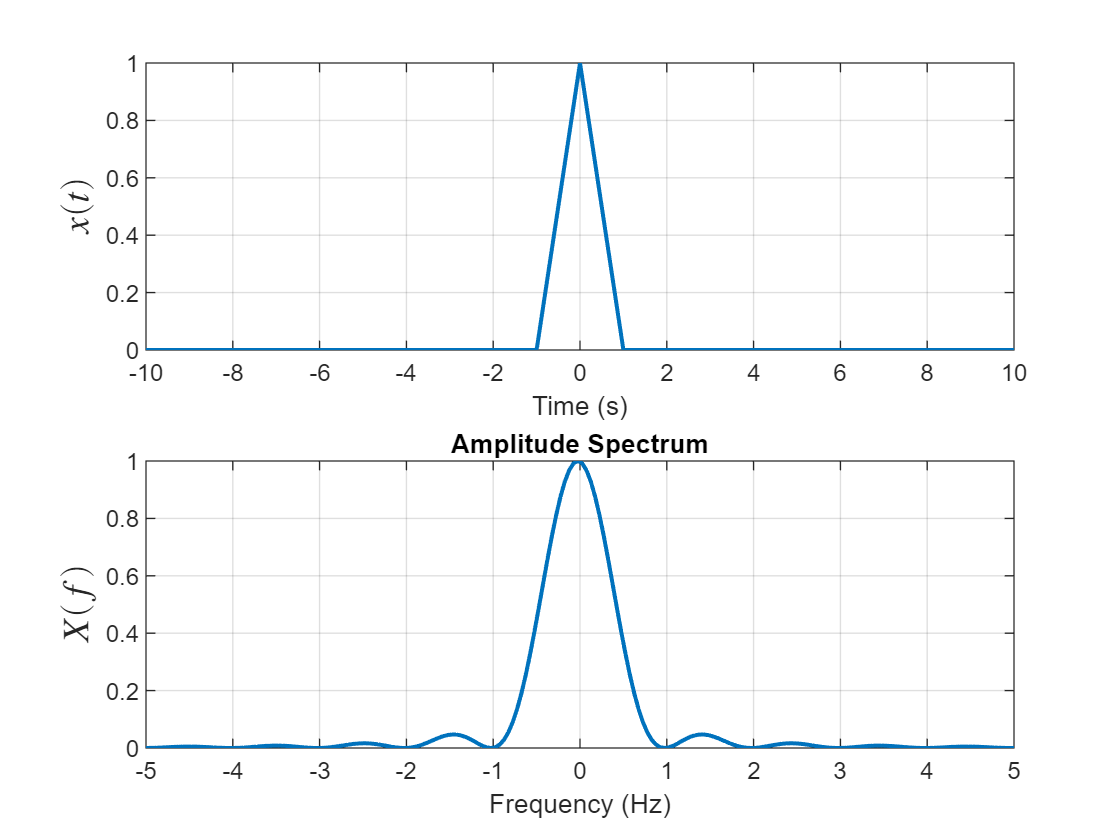

T0 = -10;
Tf = +10;
fs = 100e3;
Ts = 1/fs;
t = T0:Ts:Tf;
x = (t+1).*(t>=-1).*(t<0) + (1-t).*(t>=0).*(t<=1);

% FFT
N = length(x);
X = fftshift(fft(x))/fs;

% Frequency axis
omega = 2*pi/N * (-N/2:N/2-1);
f = (omega/(2*pi)) * fs;

% Spectrum
figure;
subplot(2,1,1)
plot(t, x, LineWidth=1.5)
xlabel('Time (s)');
ylabel('$x(t)$', 'Interpreter', 'latex','FontSize',14)
grid on

subplot(2,1,2)
plot(f,abs(X), "LineWidth",1.5);
title('Amplitude Spectrum');
xlabel('Frequency (Hz)');
ylabel('$X(f)$', 'Interpreter', 'latex', 'FontSize',14)
grid on;
xlim([-5, 5]);

### 6. LTI response

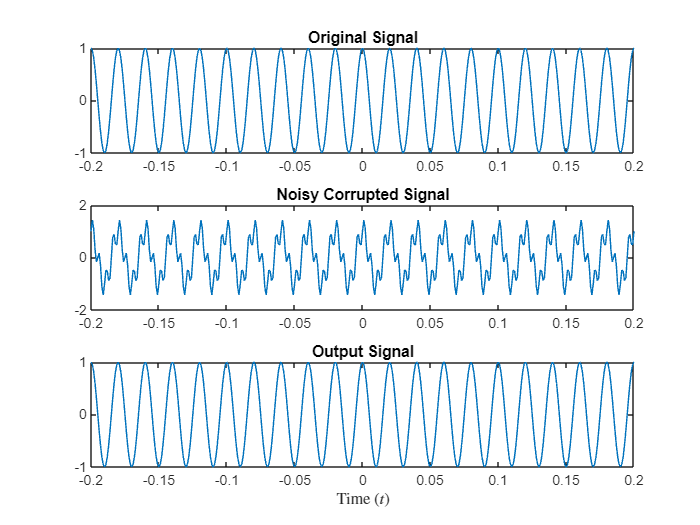

Fs = 1000; 
Ts = 1/Fs;
t = -1:Ts:1;
fm = 50;
x = cos(2*pi*fm*t);

noise = 0.5*sin(2*pi*200*t);
x_noisy = x + noise;

fc = 100;
h = 2*fc * sinc(2*fc*t);

x_filtered = conv(x_noisy, h, 'same')*Ts;

N = length(x);
f = (-N/2:N/2-1)*(Fs/N);
X_noisy = fftshift(fft(x_noisy));
X_filtered = fftshift(fft(x_filtered));
H = fftshift(fft(h));

figure;
subplot(3,1,1); 
plot(t,x); 
xlim([-0.2, 0.2])
title('Original Signal');
subplot(3,1,2); 
plot(t,x_noisy);
xlim([-0.2, 0.2])
title('Noisy Corrupted Signal'); 
subplot(3,1,3); 
plot(t, x_filtered);
xlim([-0.2, 0.2])
title('Output Signal'); 
xlabel('Time ($t$)', 'Interpreter', 'latex')

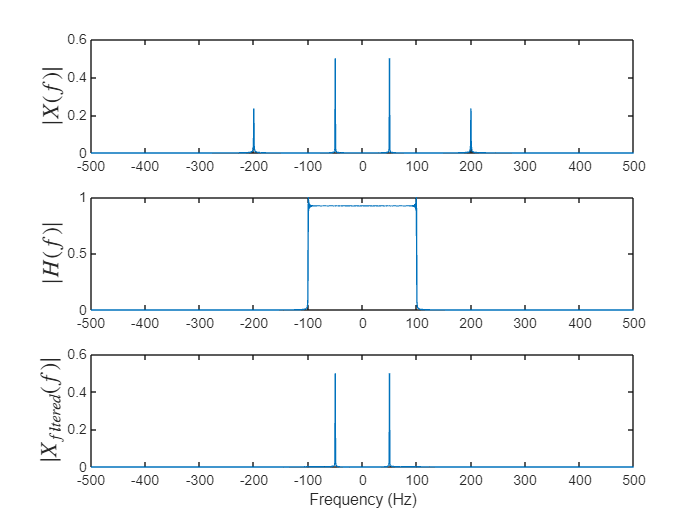

figure;
subplot(3,1,1);
plot(f, abs(X_noisy)/N);
ylabel('$|X(f)|$', 'Interpreter', 'latex', 'FontSize',14);

subplot(3,1,2);
plot(f, abs(H)/max(abs(H)));
ylabel('$|H(f)|$', 'Interpreter', 'latex', 'FontSize',14)

subplot(3,1,3);
plot(f, abs(X_filtered)/N);
xlabel('Frequency (Hz)'); ylabel('$|X_{filtered}(f)|$', 'Interpreter', 'latex', 'FontSize',14)

## References

[1] *MathWorks Documentation – MATLAB & Simulink.* Available at: https://www.mathworks.com/help/matlab

[2] https://www.mathworks.com/help/matlab/matlab_prog/create-live-scripts.html

[3] *TutorialsPoint – MATLAB Tutorial.* Available at: https://www.tutorialspoint.com/matlab